# **Speaker Recognition using Mel-Frequency Cepstrum (MFC),  FFT, and Eigendecomposition**

# Ian Walsh and Sparsh Gupta

**Dataset source:** Spoken Digit Audio dataset, retrieved from https://github.com/Jakobovski/free-spoken-digit-dataset

%QEA Fall 2022
%Ian Walsh and Sparsh Gupta Final Project
clc; clear; close all;

% Gesture Classes (Also Filenames)
speakerTypes = ["01", "02", "03", "04"];

numSpeakers = length(speakerTypes);
filesPerSpeaker= 50;

speakerLabels = zeros(numSpeakers,filesPerSpeaker);
fftFrequencies = 200;

audioArrayNames = strings(numSpeakers, filesPerSpeaker);
audioArrayFFT = zeros(fftFrequencies, 14, filesPerSpeaker, numSpeakers);

% Create labels for each
for labelMaker = 1:numSpeakers
    speakerLabels(labelMaker, 1:filesPerSpeaker) = labelMaker;
end

minSamples = 90000;

for i = 1:numSpeakers

    % Get metadata list for each directory
    fileMetadata = dir("Training Data/" + speakerTypes(i));

    for nameParser = 1:min(length(fileMetadata) - 3, filesPerSpeaker)

       % Parse out names of audio files
       audioArrayNames(i, nameParser) = fileMetadata(nameParser + 3).name;
       
       % Read the audio files (mono voltage level x numSamples)
       [f,fs] = audioread("Training Data/" + speakerTypes(i) + "/" + audioArrayNames(i, nameParser));
        
       % MFCC & FFT on audio files
       tempFFT = mfcc(f, fs);

       %Convert from complex FFT output ttempFFTo real numbers.
       %We only care about the first 20k samples as they correspond to a DC-20kHz frequency spectrum
       audioArrayFFT(1:size(tempFFT, 1), :, nameParser, i) = tempFFT;

       %if(size(tempFFT, 1) < minSamples)
       if(size(tempFFT, 1) < minSamples)
           minSamples = size(tempFFT, 1);
       end

    end
end

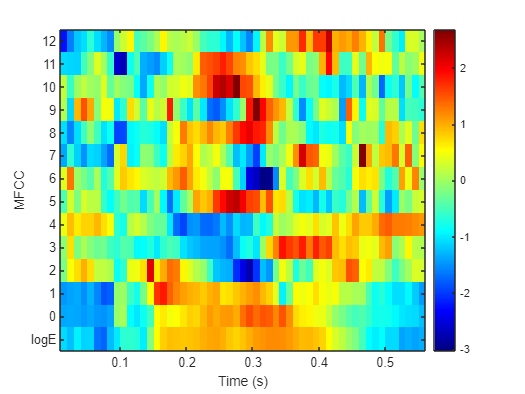

% MFCC example spectrum heatmap
mfcc(f, fs)

numTrain = filesPerSpeaker / 2;
numTest = filesPerSpeaker / 2;

% data initialization
trainData = audioArrayFFT(1:minSamples, :, 1:numTrain, :);
testData  = audioArrayFFT(1:minSamples, :, numTrain:numTrain+numTest, :);

train_data2 = zeros(minSamples * 14, numTrain, numSpeakers);
test_data2 = zeros(minSamples * 14, numTest, numSpeakers);

% data labels initialization
speakersLabels_train = zeros(numTrain, numSpeakers);
speakersLabels_test = zeros(numTest, numSpeakers);

for i = 1:numTrain
    for j = 1:numSpeakers
        temptemp = trainData(:, :, i, j);
        train_data2(:,i, j) = reshape(temptemp, [], 1);
    end
end

for i = 1:numTest
    for j = 1:numSpeakers
        temptemp = testData(:, :, i, j);
        test_data2(:,i, j) = reshape(temptemp, [], 1);
    end
end

train_data = reshape(train_data2, [], numTrain * numSpeakers);
test_data = reshape(test_data2, [], numTest * numSpeakers);

 
% data manipulation
for i=1:numSpeakers

    for k=1:numTrain
        speakersLabels_train(k,i) = speakerLabels(i,k);
    end
    for k=1:numTest
        speakersLabels_test(k,i) = speakerLabels(i,k);
    end

end

% number of files in each dataset(equal split between train data & test data)
n = numSpeakers * numTrain;


% reshape data labels
speakersLabels_train = reshape(speakersLabels_train, [], 1);

% eigendecomposition

c_train = train_data' * train_data;

[V_train, D_train] = eig(c_train);

U = train_data * V_train;

% training set weights
weights_train = zeros(n, n);

for i=1:n
    weights_train(:,i) = project(train_data(:,i), U, n);
end

% prediction on test set
test_pred = zeros(n, 1);

for i=1:n
    test_pred(i) = predict_speaker(test_data(:,i), U, n, weights_train, speakersLabels_train);
end

speakersLabels_test = reshape(speakersLabels_test, [], 1);

% Accuracy of the model on the test set
Accuracy = sum(test_pred == speakersLabels_test,'all')/numel(speakersLabels_test)

Accuracy = 0.9100

function [weights] = project(train_data, U, n) 

    weights = zeros(n, 1);

    for i=1:n
        weights(i) = U(:,i)' * train_data;
    end

end

function [pred] = predict_speaker(test_data, U, n, weights_train, train_labels)

    weights_test = project(test_data, U, n);
    pred = -1;
    theta = inf;

    for i=1:n

        dist = (weights_test - weights_train(:,i))' * (weights_test - weights_train(:,i));

        if (dist < theta)
            theta = dist;
            pred = train_labels(i);
        end

    end

end